## Loading in data

subjectNames = {
    'nstdb/118e24';
    'nstdb/118e18';
    'nstdb/118e12';
    'nstdb/118e06';
    'nstdb/118e00';
    'nstdb/118e_6';
    'nstdb/119e24';
    'nstdb/119e18';
    'nstdb/119e12';
    'nstdb/119e06';
    'nstdb/119e00';
    'nstdb/119e_6'
};
%set number of files
files = length(subjectNames);
%Initialize Arrays
Fs = zeros(files,1);
ecg = cell(files,1);
tm = cell(files,1);
rr = cell(files,1);
tm2 = cell(files,1);
%loop through all file names
for fi = 1:files
    [ecg{fi,1},Fs(fi),tm{fi,1}]= rdsamp(subjectNames{fi,1},1);
    [rr{fi,1},tm2{fi,1}]=ann2rr(subjectNames{fi,1},'atr');
end 
%Note: Noise was added beginning after the first 5 minutes of each record, during two-minute segments alternating with two-minute clean segments.
save('nstdb_dataset','ecg','Fs','tm','rr','tm2');

## Plotting Data

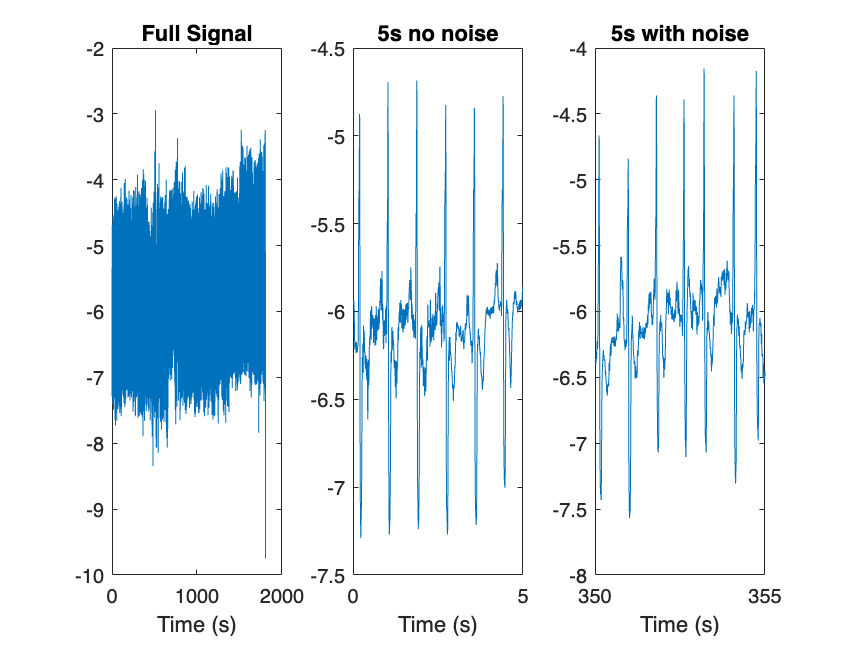

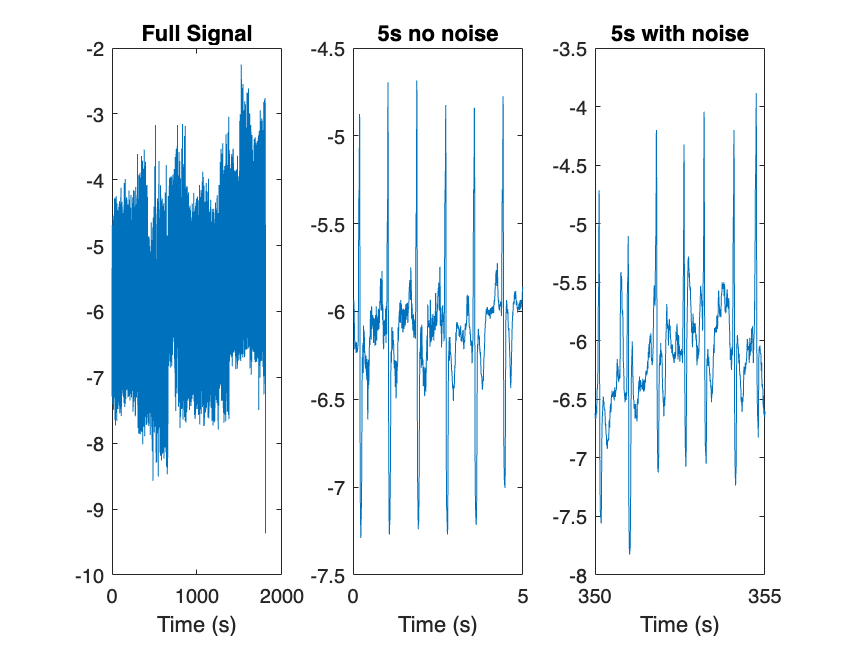

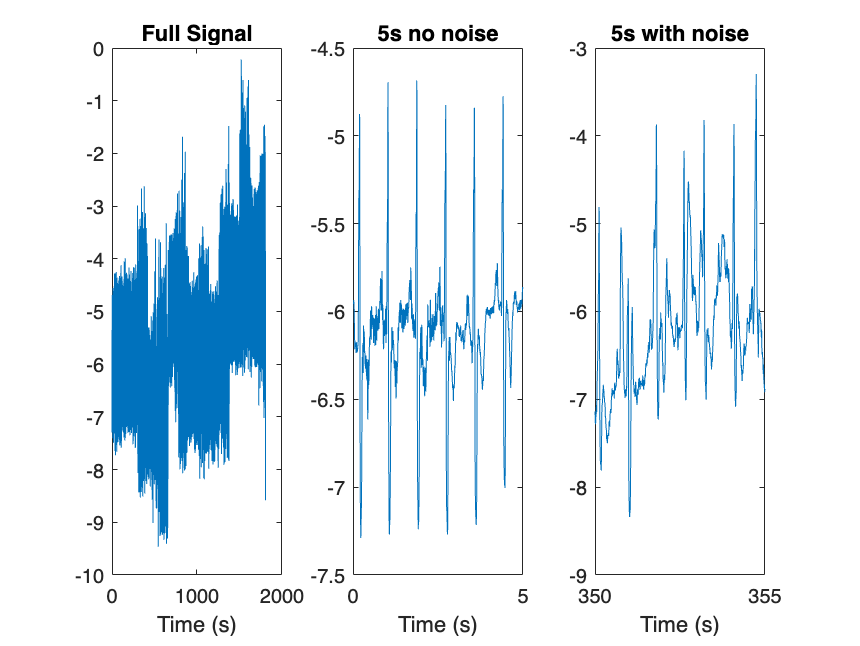

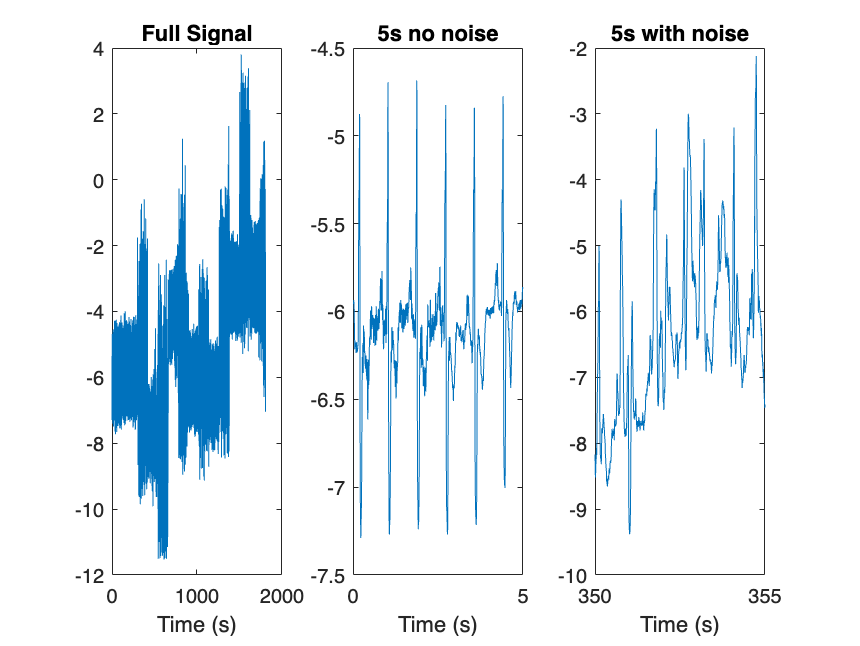

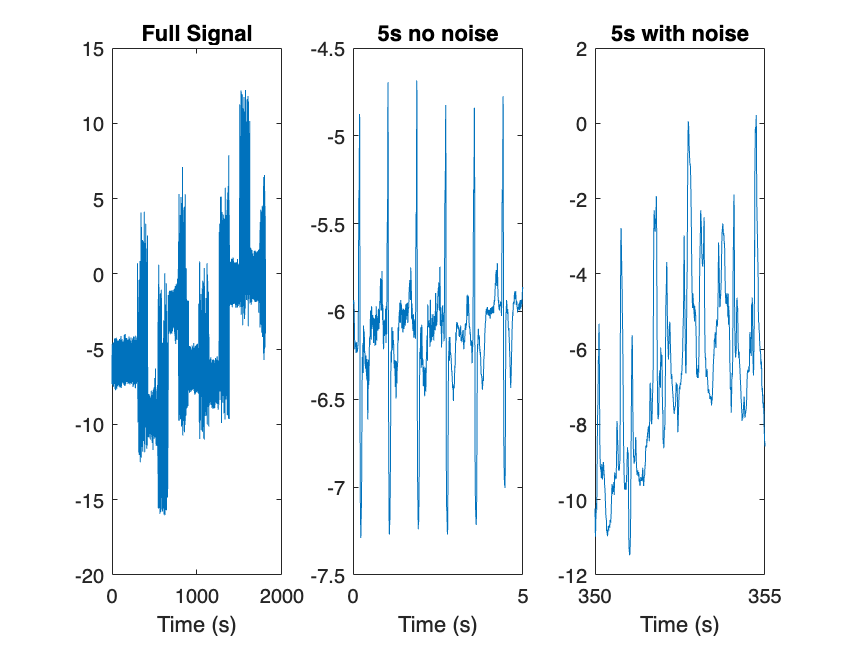

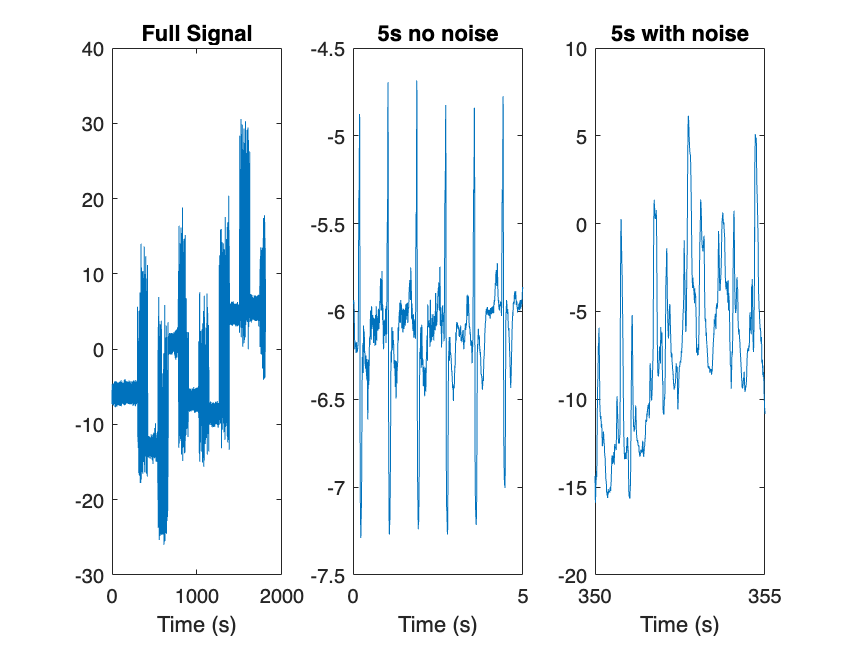

%Example Plot of 118e24
for i = 1:6
    figure; 
    subplot(1,3,1)
    plot(tm{i,1},ecg{i,1})
    title("Full Signal");
    xlabel('Time (s)')
    subplot(1,3,2)
    plot(tm{i,1},ecg{i,1})
    xlim([0,5])
    title("5s no noise");
    xlabel('Time (s)')
    subplot(1,3,3)
    plot(tm{i,1},ecg{i,1})
    xlim([350,355])
    title("5s with noise");
    xlabel('Time (s)')
end 

## First Attempt at PCA

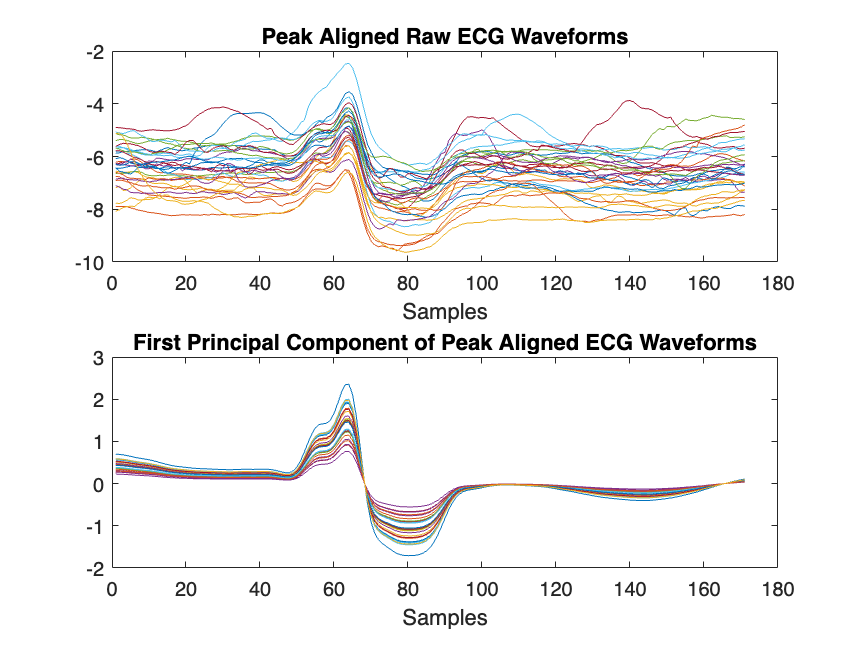


file_idx = 4; 
data = ecg{file_idx,1};
n = length(data); 
fs = Fs(file_idx,1);
this_rr = rr{file_idx,1};
this_tm = tm2{file_idx,1};
%Split into segments by peaks
samp_per_seg = min(this_rr);
segs = length(this_rr); 
data_ar = [];
for i = 2:length(this_tm)
    t = this_tm(i);
    data_row = data(t-60:t+samp_per_seg-61)'; 
    data_ar = [data_ar; data_row];
end 
figure;
subplot(2,1,1);
plot(data_ar(360:390,:)'); 
title('Peak Aligned Raw ECG Waveforms')
xlabel('Samples')
[coeff, score, latent, ~, explained] = pca(data_ar');
n = 1; % Example: Use the first 4 principal components
reconstructed_signal = score(:, 1:n) * coeff(:, 1:n)';
reconstructed_signal = reconstructed_signal';
subplot(2,1,2);
plot(reconstructed_signal(360:390,:)');
title('First Principal Component of Peak Aligned ECG Waveforms')
xlabel('Samples')

Modifying so includes multiple ECG waveforms

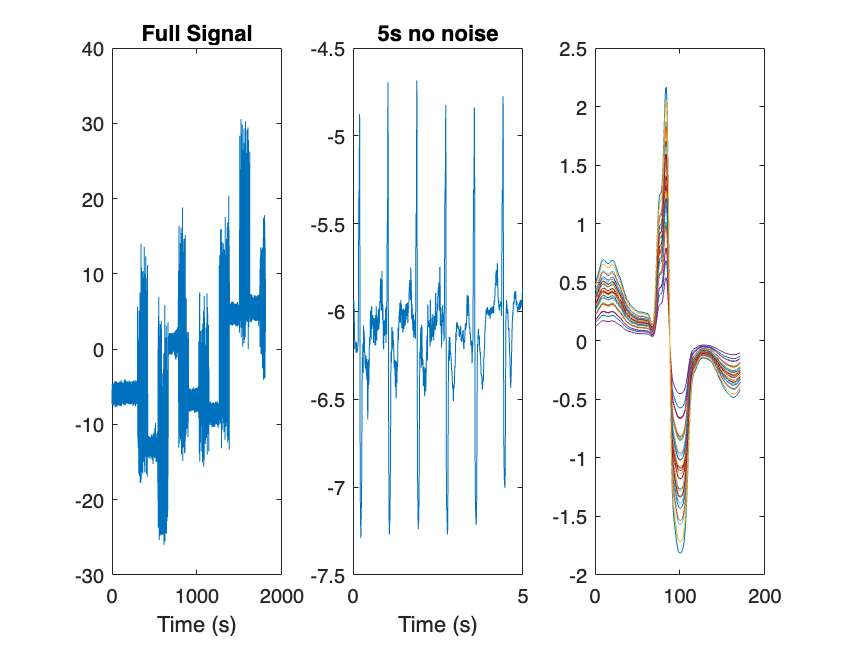


file_idx = 4; 
data = ecg{file_idx,1};
n = length(data); 
fs = Fs(file_idx,1);
this_rr = rr{file_idx,1};
this_tm = tm2{file_idx,1};
%Split into segments by peaks
samp_per_seg = min(this_rr);
segs = length(this_rr); 
data_ar = [];
for i = 2:length(this_tm)-1
    t = this_tm(i);
    data_row = data(t-80:t+samp_per_seg-81,1)'; 
    data_ar = [data_ar; data_row];
end 
plot(data_ar(360:390,:)'); 

[coeff, score, latent, ~, explained] = pca(data_ar');
n = 1; % Example: Use the first 4 principal components
reconstructed_signal = score(:, 1:n) * coeff(:, 1:n)';
reconstructed_signal = reconstructed_signal';
plot(reconstructed_signal(360:390,:)');